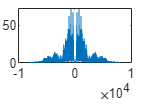

ctof_fq = 50;
[sig, fs] = audioread('C_01_02.wav');
N = [4 6 8 16];
fbe = 200; 
fen = 7000; 
but_order = 4;

figure;
f = linspace(-fs/2, fs/2, length(sig));
sig_fft = fftshift(fft(sig));
plot(f, abs(sig_fft));

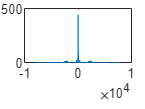


n_bands = 8;
if(size(sig,2)==1) 
    sig = sig';
end
f2d = @(f) log10(f/165.4 + 1) / 0.06;
d2f = @(d) 165.4 * (10.^(0.06*d) - 1);

out = zeros(1,length(sig));

dbe = f2d(fbe); den = f2d(fen);
ds = linspace(dbe, den, n_bands+1);
[lpf_b, lpf_a] = butter(but_order, ctof_fq/(fs/2));
t = (0:length(sig)-1)/fs;

i = 4;
d0 = ds(i); d1 = ds(i+1); 
f0 = d2f(d0); f1 = d2f(d1);
fmid = (f0+f1)/2;
[bpf_b, bpf_a] = butter(but_order, [f0 f1]/(fs/2));

figure;
road = abs(filter(bpf_b, bpf_a, sig));
road_fft = fftshift(fft(road));
plot(f, abs(road_fft));

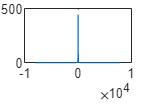


figure;
road_lpf = filter(lpf_b, lpf_a, road);
road_lpf_fft = fftshift(fft(road_lpf));
plot(f, abs(road_lpf_fft));

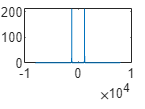


carry = sin(2*pi*fmid*t);
out = out + carry.*road_lpf;

figure;
out_fft = fftshift(fft(out));
plot(f, abs(out_fft));

audiowrite( "lpf_50.wav", out, fs);


clear; clc;

ctof_fq = 400;
[sig, fs] = audioread('C_01_02.wav');
N = [4 6 8 16];
fbe = 200; 
fen = 7000; 
but_order = 4;

figure;
f = linspace(-fs/2, fs/2, length(sig));
sig_fft = fftshift(fft(sig));
plot(f, abs(sig_fft));


n_bands = 8;
if(size(sig,2)==1) 
    sig = sig';
end
f2d = @(f) log10(f/165.4 + 1) / 0.06;
d2f = @(d) 165.4 * (10.^(0.06*d) - 1);

out = zeros(1,length(sig));

dbe = f2d(fbe); den = f2d(fen);
ds = linspace(dbe, den, n_bands+1);
[lpf_b, lpf_a] = butter(but_order, ctof_fq/(fs/2));
t = (0:length(sig)-1)/fs;

i = 4;
d0 = ds(i); d1 = ds(i+1); 
f0 = d2f(d0); f1 = d2f(d1);
fmid = (f0+f1)/2;
[bpf_b, bpf_a] = butter(but_order, [f0 f1]/(fs/2));

figure;
road = abs(filter(bpf_b, bpf_a, sig));
road_fft = fftshift(fft(road));
plot(f, abs(road_fft));

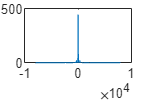


figure;
road_lpf = filter(lpf_b, lpf_a, road);
road_lpf_fft = fftshift(fft(road_lpf));
plot(f, abs(road_lpf_fft));

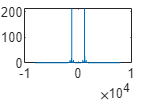


carry = sin(2*pi*fmid*t);
out = out + carry.*road_lpf;

figure;
out_fft = fftshift(fft(out));
plot(f, abs(out_fft));


audiowrite( "lpf_400.wav", out, fs);